% PHYS 434
% LAB 5
% Jin Kyoung Lee

## Higgs data

%{
The training data containes 14 features:
pt, eta, phi, mass, ee2, ee3, d2, angularity, t1, t2, t3, t21, t32,
KitDeltaR
%}

% Importing data
% Signal dataset
h5disp("LAB/Higgs_data/Sample_pt_250_500/higgs_100000_pt_250_500.h5")

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


signalData = h5read("LAB/Higgs_data/Sample_pt_250_500/higgs_100000_pt_250_500.h5","/higgs_100000_pt_250_500");
% Background dataset
h5disp("LAB/Higgs_data/Sample_pt_250_500/qcd_100000_pt_250_500.h5")

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


backgroundData = h5read("LAB/Higgs_data/Sample_pt_250_500/qcd_100000_pt_250_500.h5","/qcd_100000_pt_250_500");

## pt

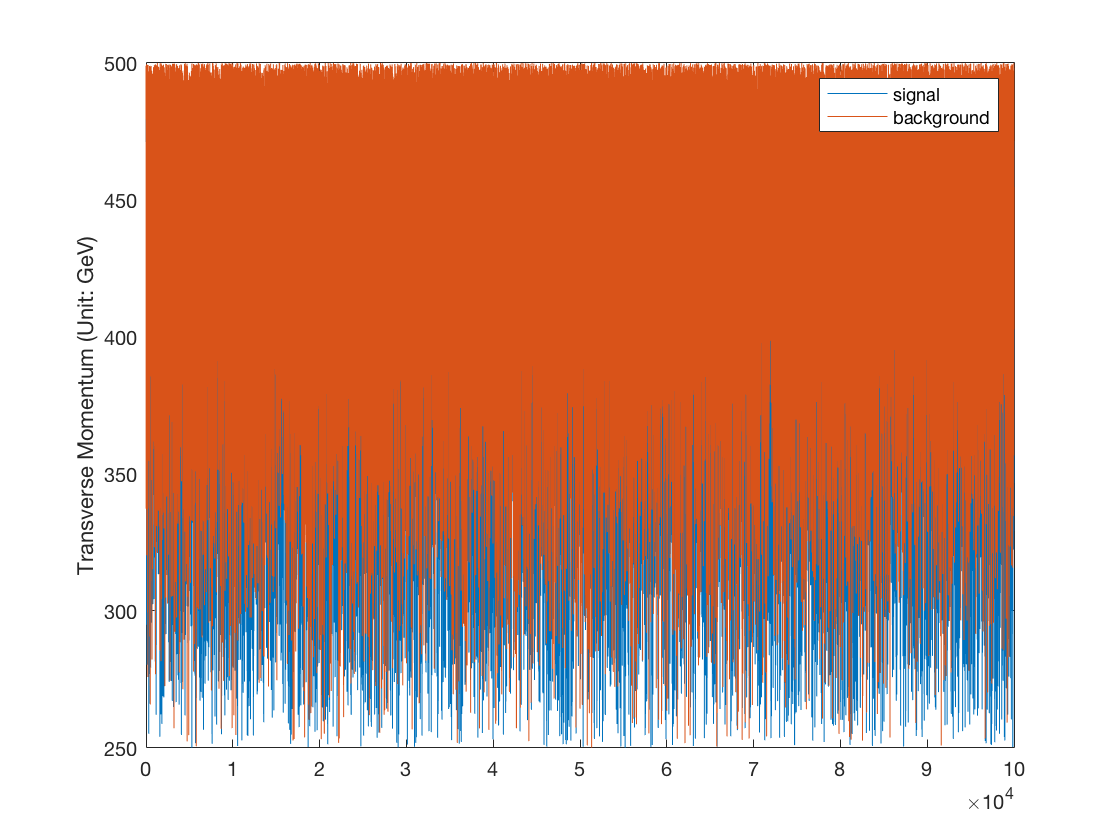

% Transverse momentum (xy-plane)
ptSignal = signalData(1,1:100000);
plot(ptSignal)
hold on
ptBackground = backgroundData(1,1:100000);
plot(ptBackground)
legend('signal','background')
hold off
ylabel('Transverse Momentum (Unit: GeV)')

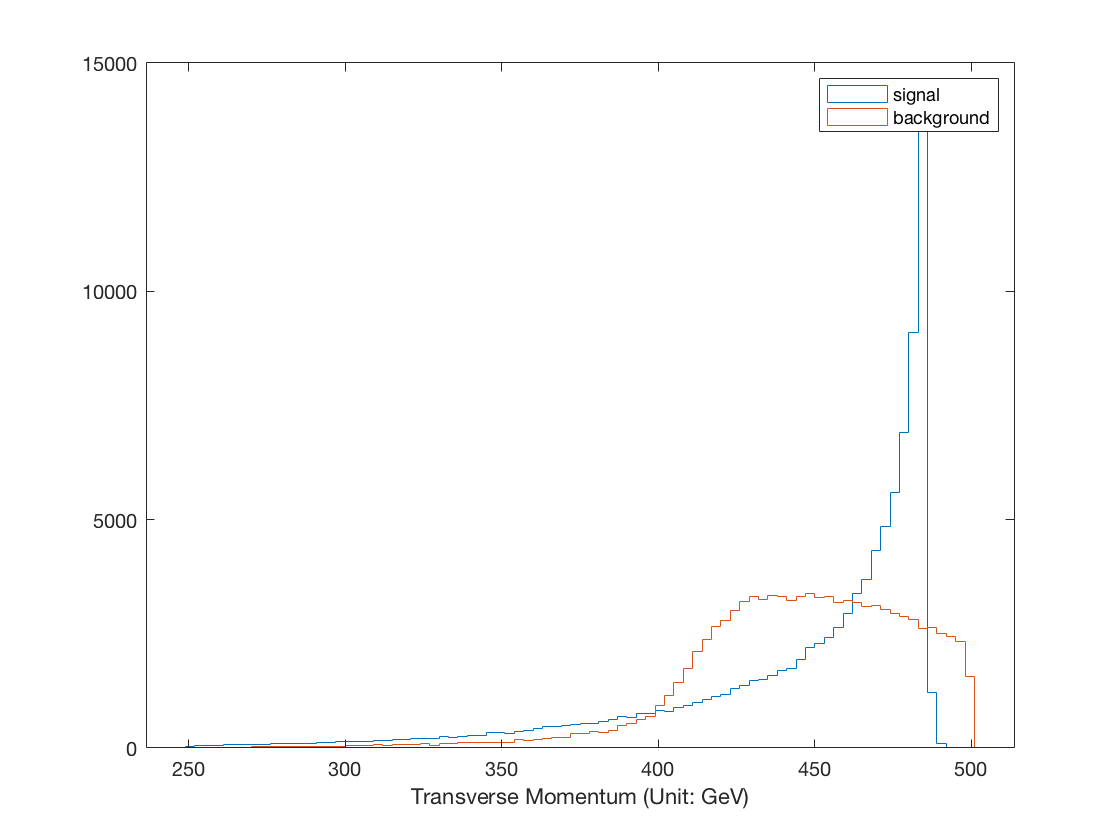

histogram(ptSignal,'DisplayStyle','Stairs')
hold on
histogram(ptBackground,'DisplayStyle','Stairs')
legend('signal','background')
hold off
xlabel('Transverse Momentum (Unit: GeV)')

## eta

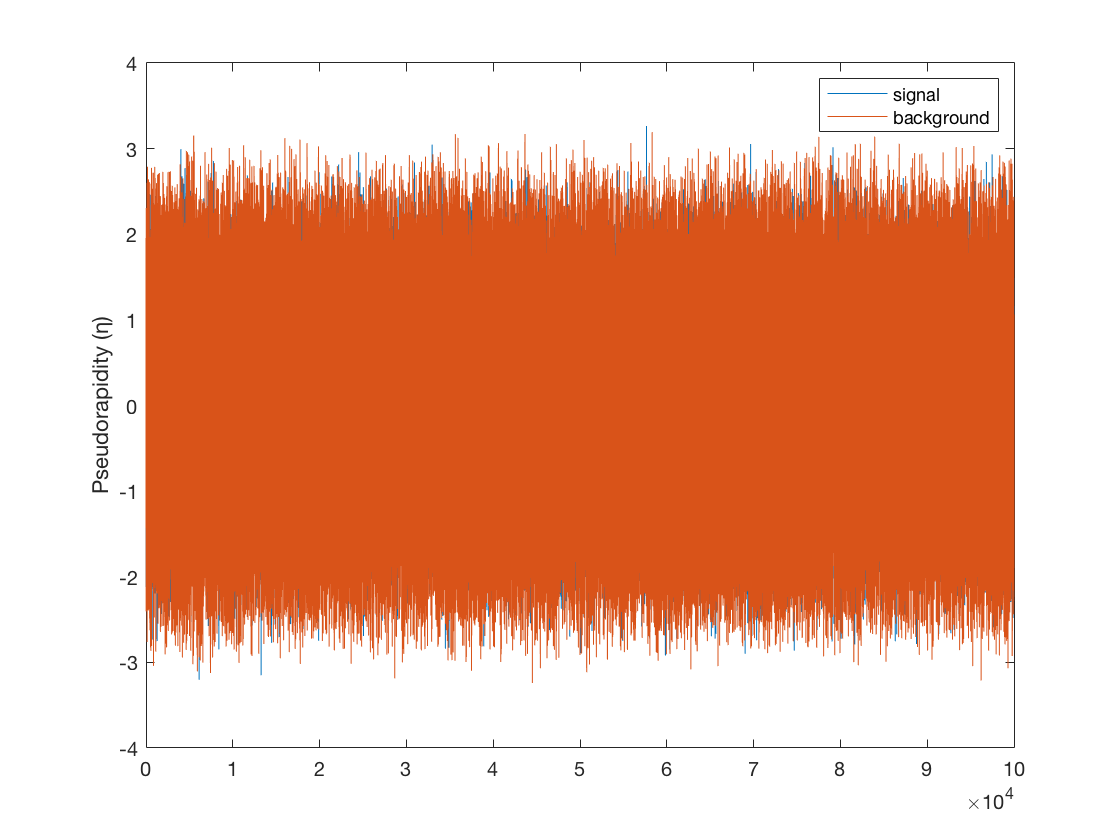

% Pseudorapidity (η)
etaSignal = signalData(2,1:100000);
plot(etaSignal)
hold on
etaBackground = backgroundData(2,1:100000);
plot(etaBackground)
legend('signal','background')
hold off
ylabel('Pseudorapidity (η)')

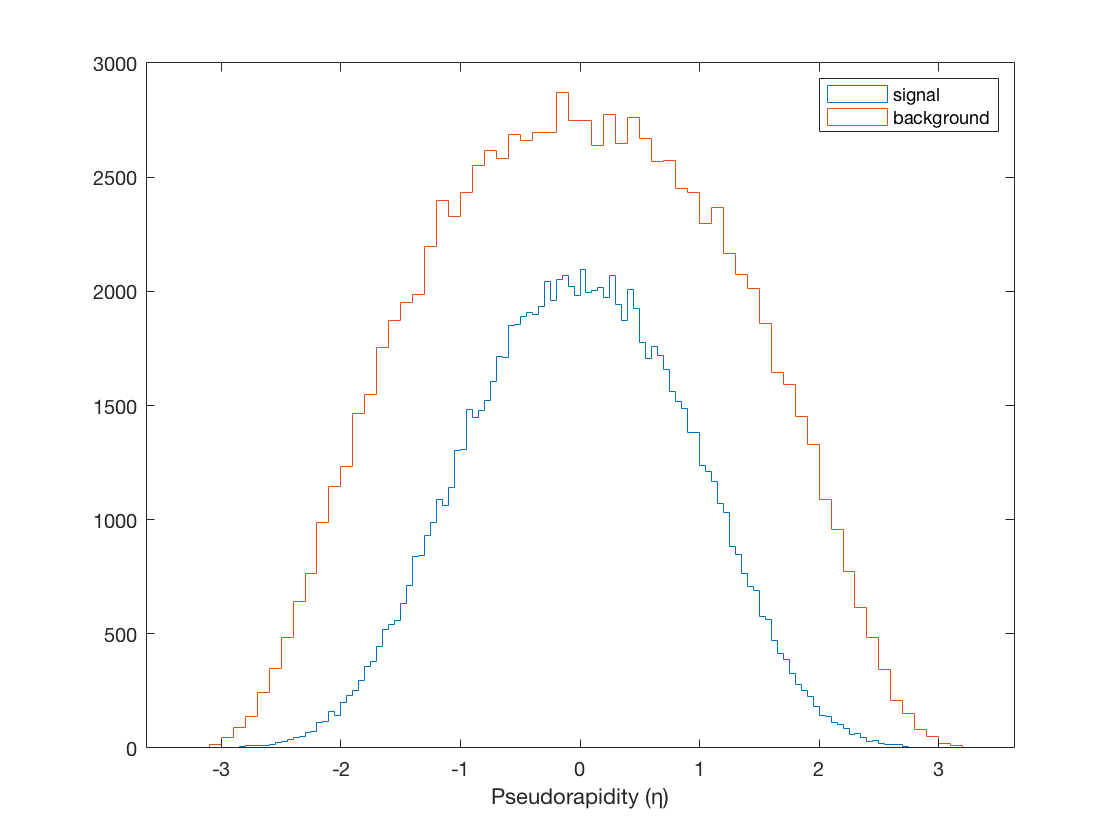

histogram(etaSignal,'DisplayStyle','Stairs')
hold on
histogram(etaBackground,'DisplayStyle','Stairs')
legend('signal','background')
hold off
xlabel('Pseudorapidity (η)')

## phi

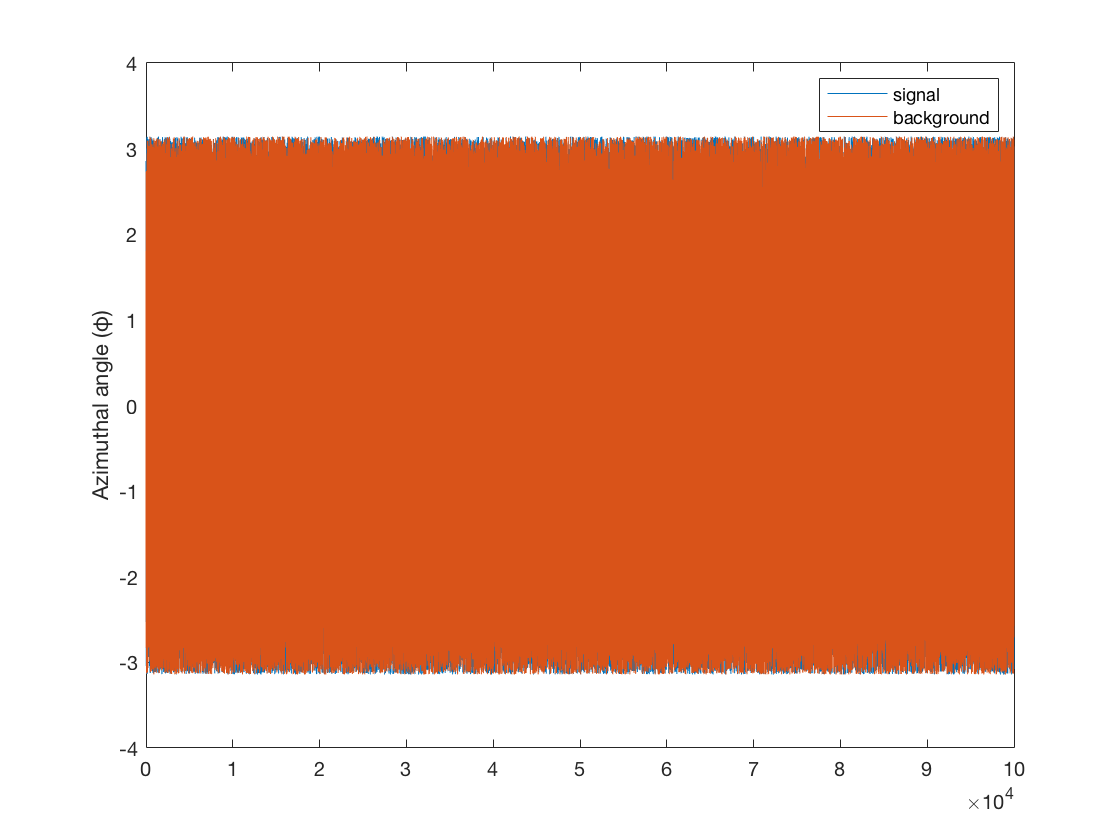

% Azimuthal angle around the z-axis (φ) (in cylindrical coordinates)
phiSignal = signalData(3,1:100000);
plot(phiSignal)
hold on
phiBackground = backgroundData(3,1:100000);
plot(phiBackground)
legend('signal','background')
hold off
ylabel('Azimuthal angle (φ)')

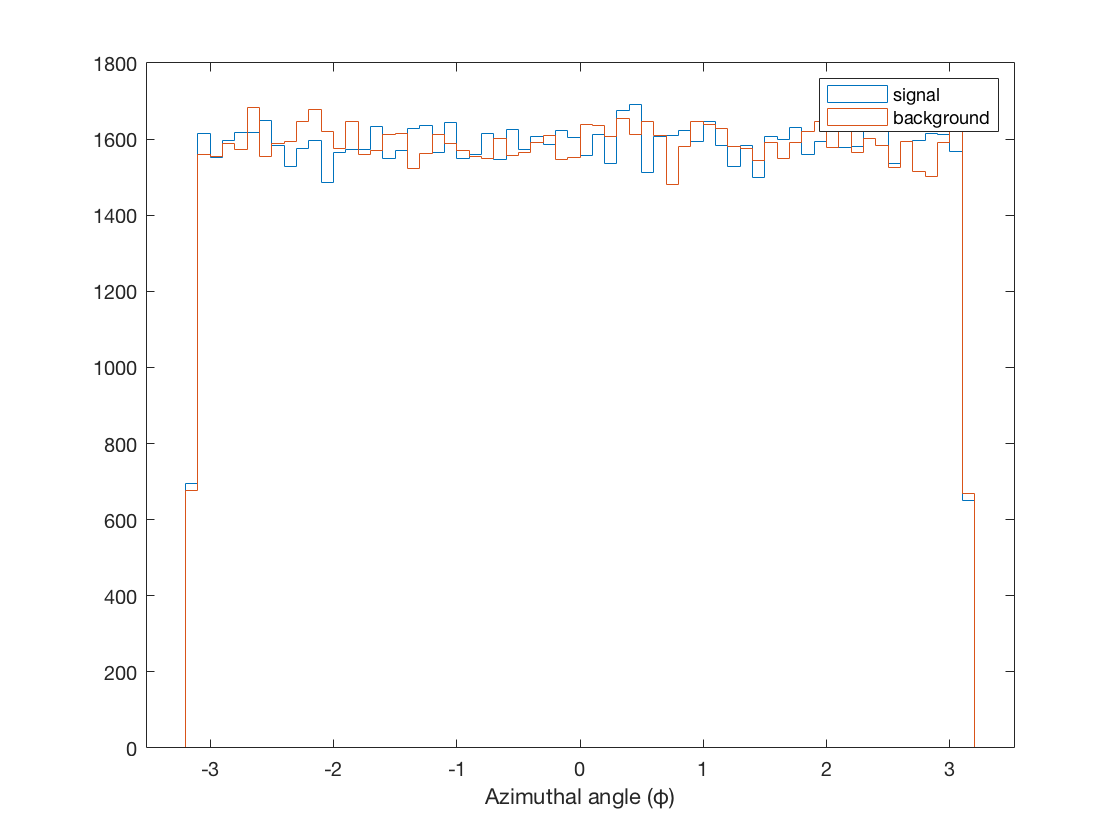

histogram(phiSignal,'DisplayStyle','Stairs')
hold on
histogram(phiBackground,'DisplayStyle','Stairs')
legend('signal','background')
hold off
xlabel('Azimuthal angle (φ)')

## mass

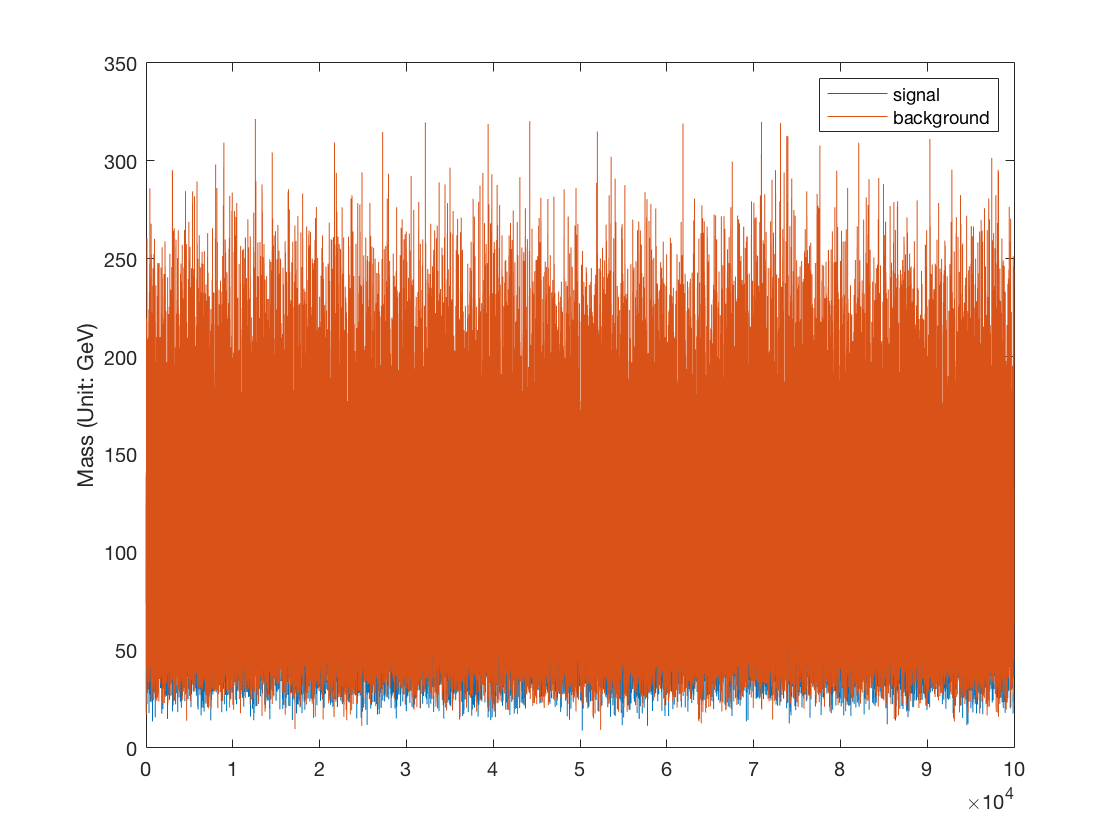

% Invariant mass: invariant mass of the two pieces, which, for example, are
% p_t1(the highest transverse momentum) and p_t2(the lowest transverse
% momentum)
massSignal = signalData(4,1:100000);
plot(massSignal)
hold on
massBackground = backgroundData(4,1:100000);
plot(massBackground)
legend('signal','background')
hold off
ylabel('Mass (Unit: GeV)')

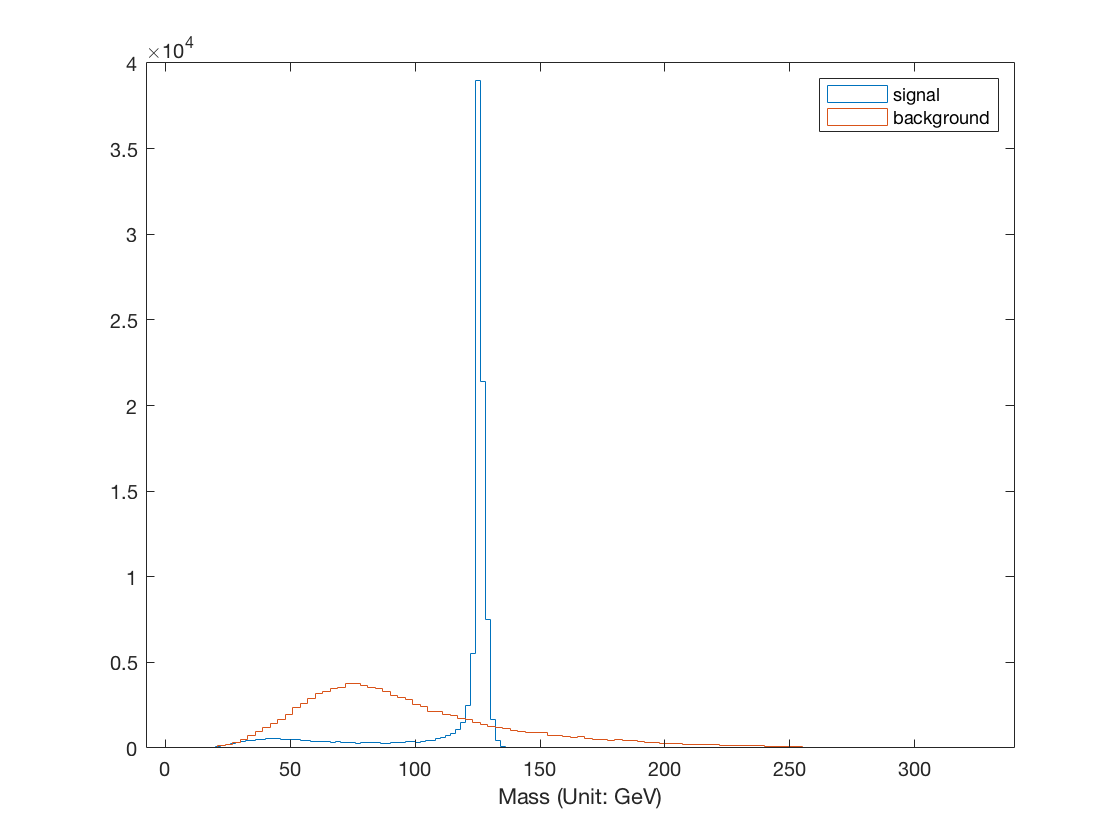

histogram(massSignal,'DisplayStyle','Stairs')
hold on
histogram(massBackground,'DisplayStyle','Stairs')
legend('signal','background')
hold off
xlabel('Mass (Unit: GeV)')

## ee2

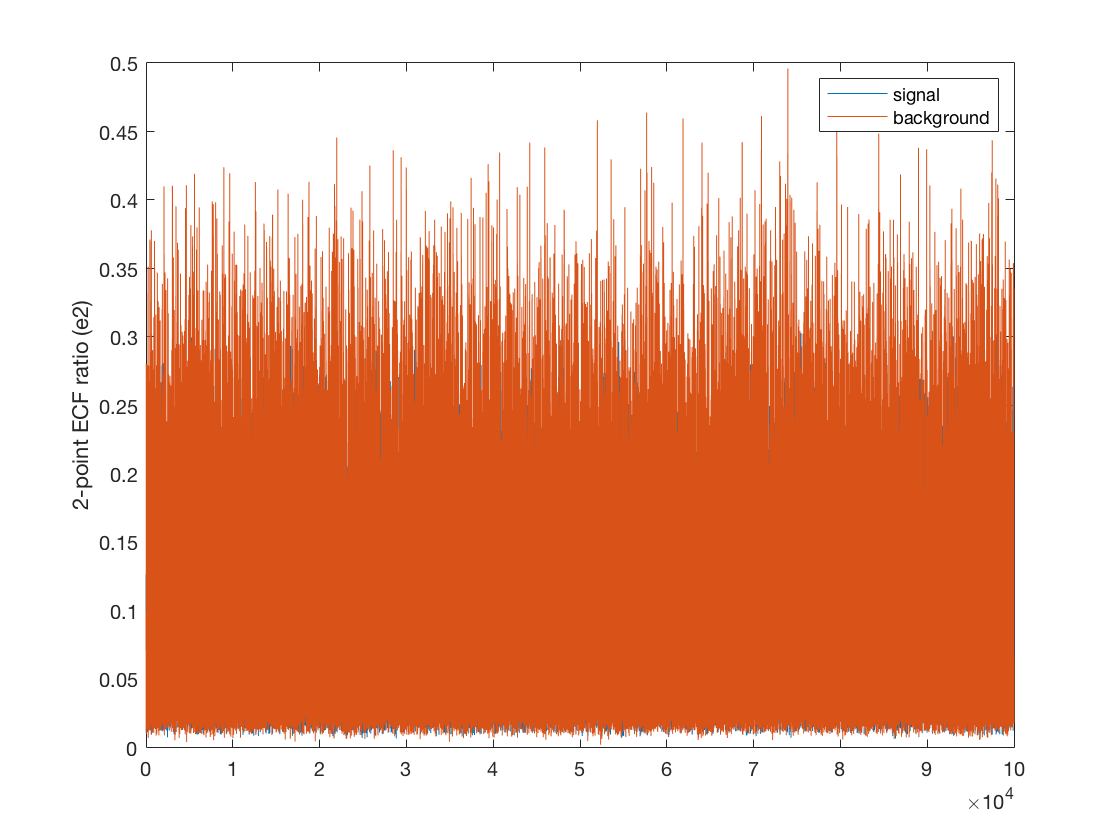

% 2-point ECF(Energy Correlation Functions) ratio
% Energy correlation function for jet J is the sum of transverse momentum.
% Therefore, 2-point ECF will be the sum over multiplication of transverse
% momentum of constituents i and j in the jet J.
ee2Signal = signalData(5,1:100000);
plot(ee2Signal)
hold on
ee2Background = backgroundData(5,1:100000);
plot(ee2Background)
legend('signal','background')
hold off
ylabel('2-point ECF ratio (e2)')

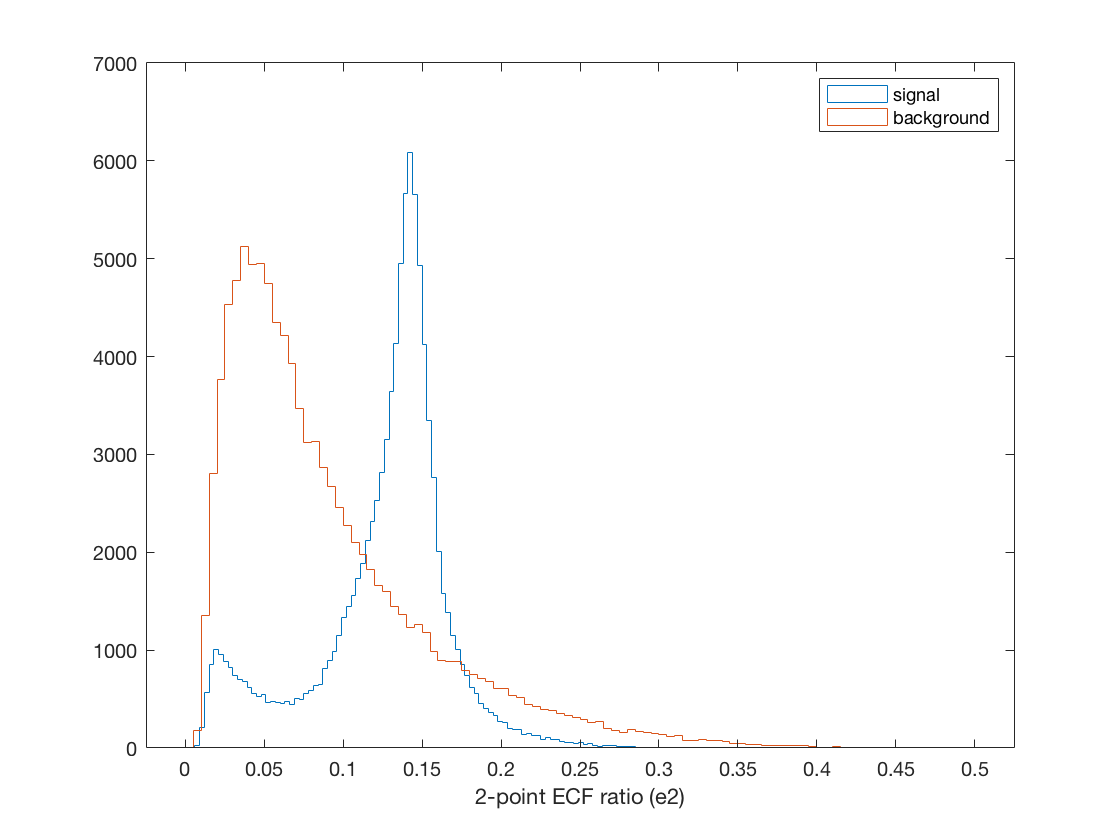

histogram(ee2Signal,'DisplayStyle','Stairs')
hold on
histogram(ee2Background,'DisplayStyle','Stairs')
legend('signal','background')
hold off
xlabel('2-point ECF ratio (e2)')

## ee3

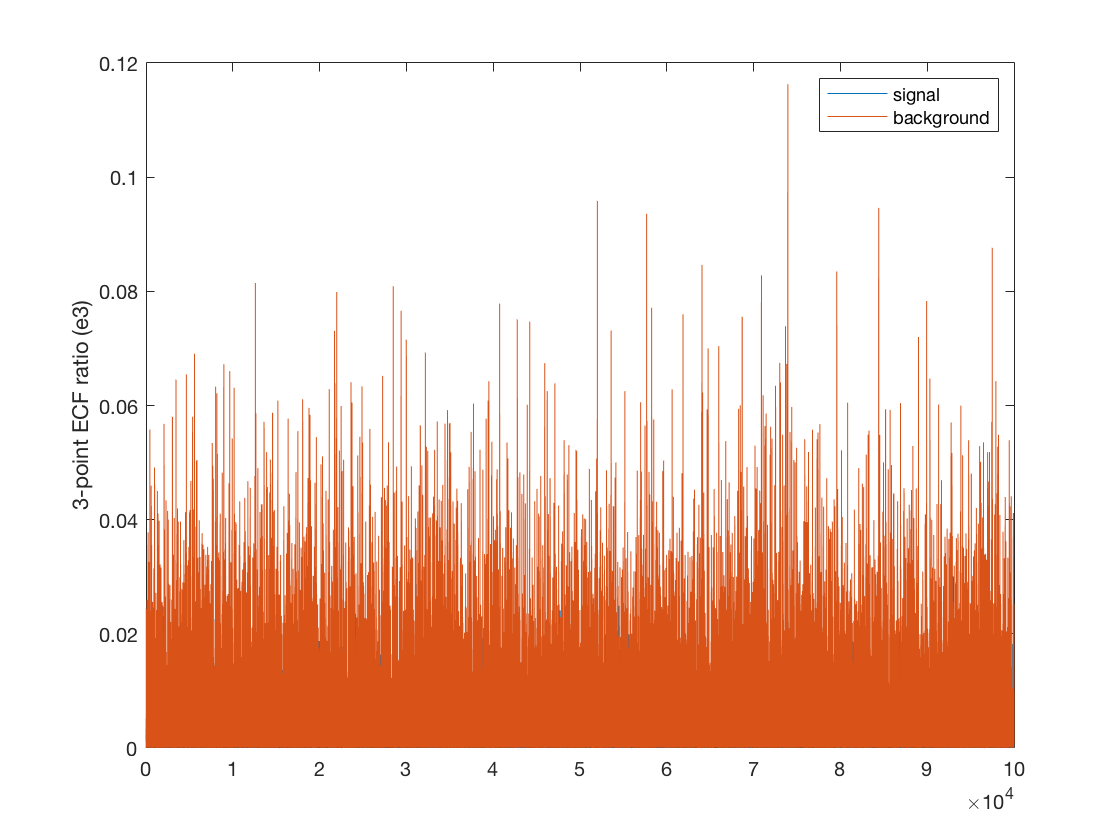

% 3-point ECF(Energy Correlation Functions) ratio
% 3-point ECF will be the sum over multiplication of transverse
% momentum of constituents i, j, and k in the jet J.
ee3Signal = signalData(6,1:100000);
plot(ee3Signal)
hold on
ee3Background = backgroundData(6,1:100000);
plot(ee3Background)
legend('signal','background')
hold off
ylabel('3-point ECF ratio (e3)')

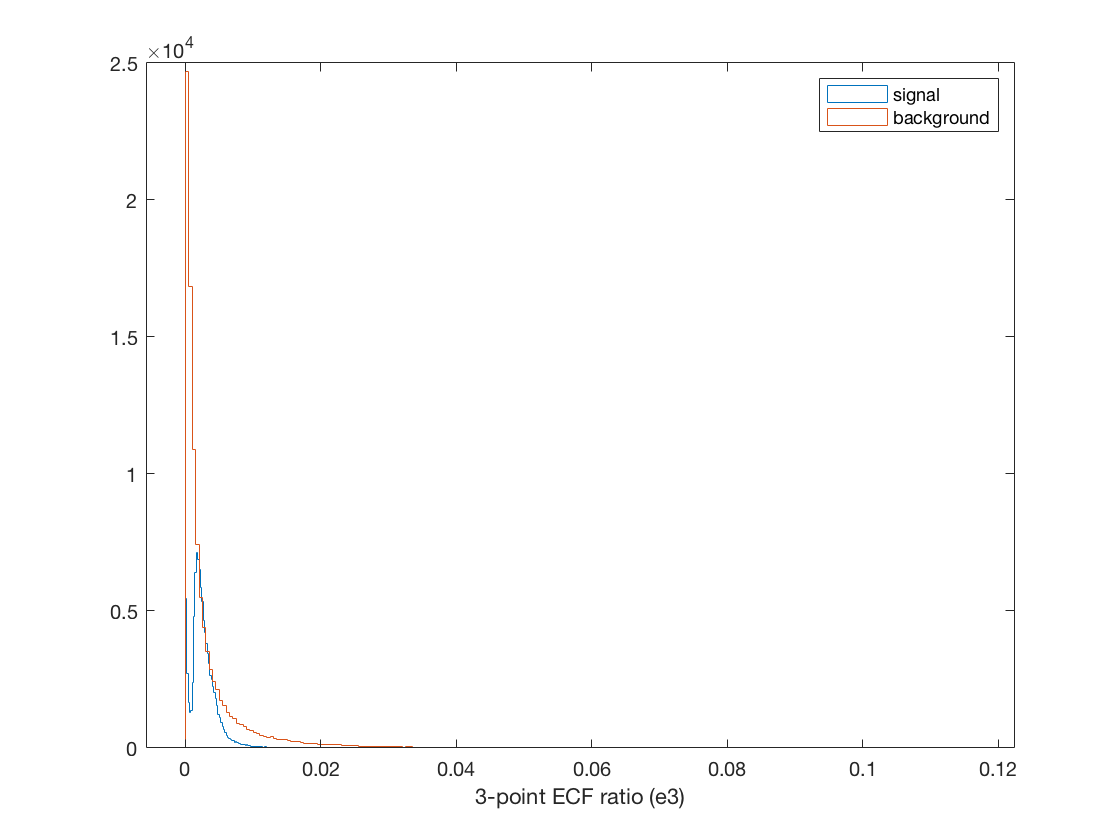


histogram(ee3Signal,'DisplayStyle','Stairs')
hold on
histogram(ee3Background,'DisplayStyle','Stairs')
legend('signal','background')
hold off
xlabel('3-point ECF ratio (e3)')

## d2

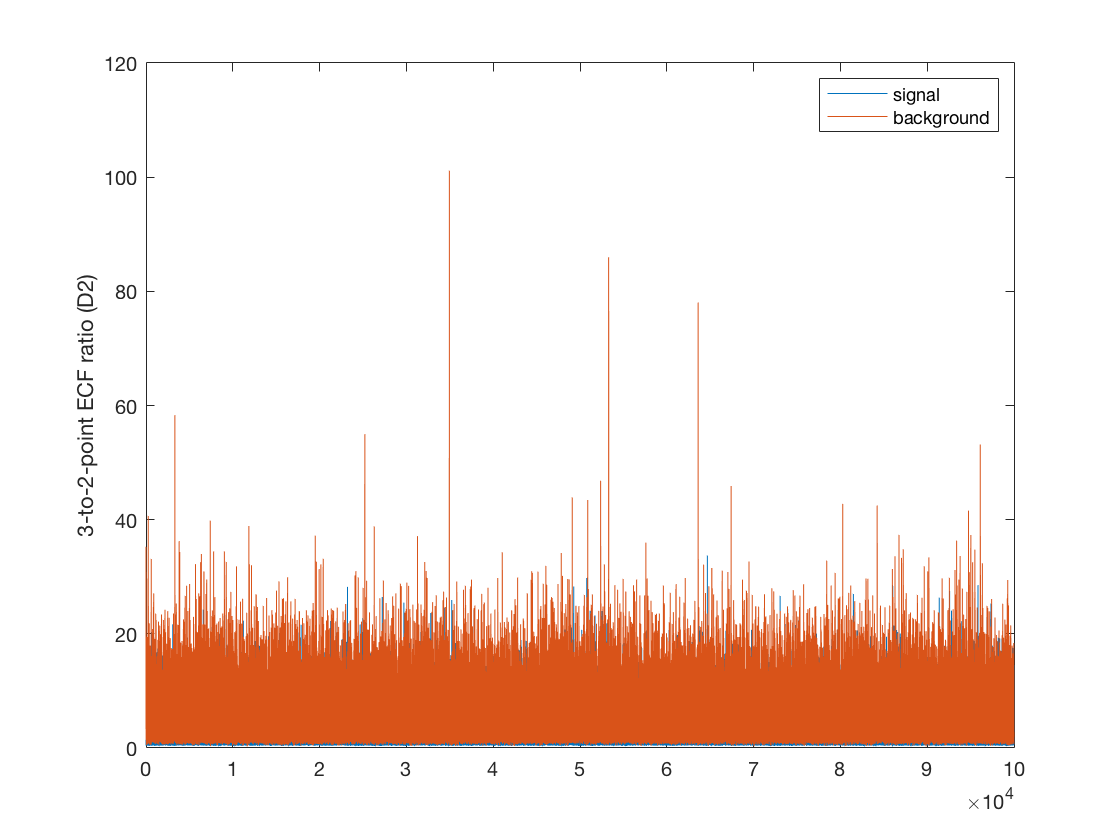

% 3-to-2-point ECF(Energy Correlation Functions) ratio
d2Signal = signalData(7,1:100000);
plot(d2Signal)
hold on
d2Background = backgroundData(7,1:100000);
plot(d2Background)
legend('signal','background')
hold off
ylabel('3-to-2-point ECF ratio (D2)')

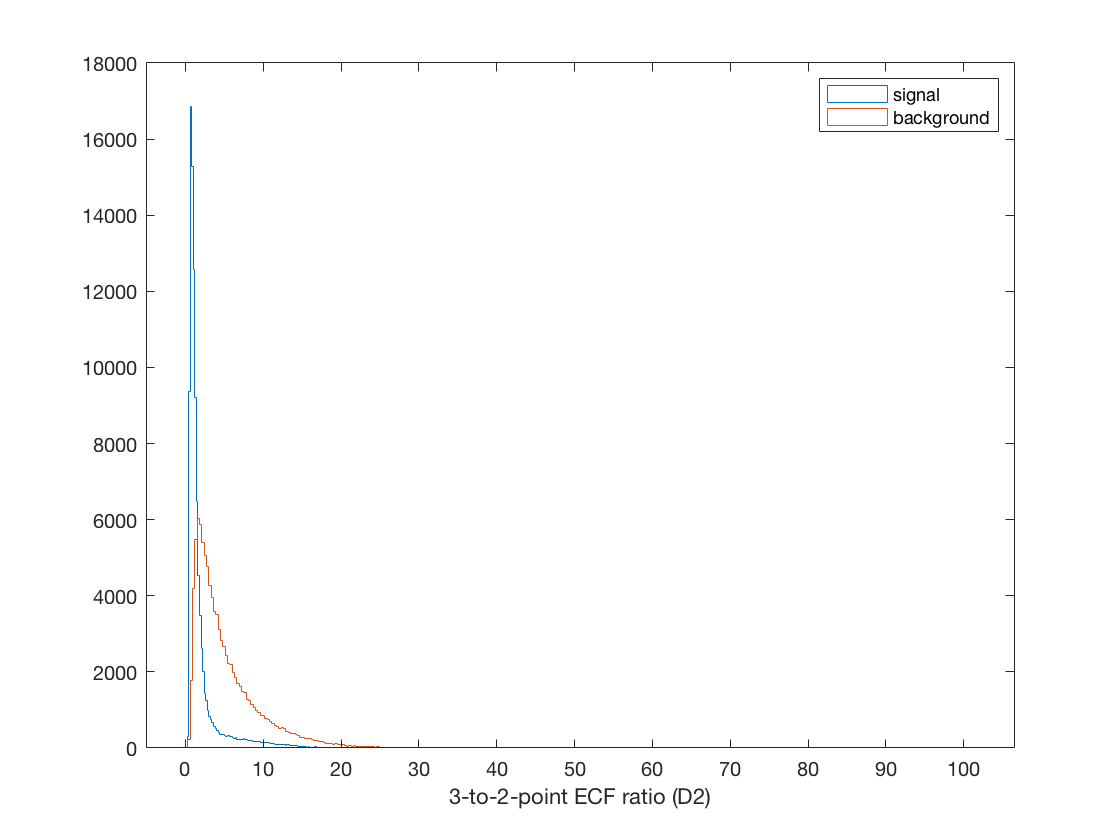

histogram(d2Signal,'DisplayStyle','Stairs')
hold on
histogram(d2Background,'DisplayStyle','Stairs')
legend('signal','background')
hold off
xlabel('3-to-2-point ECF ratio (D2)')

## angularity

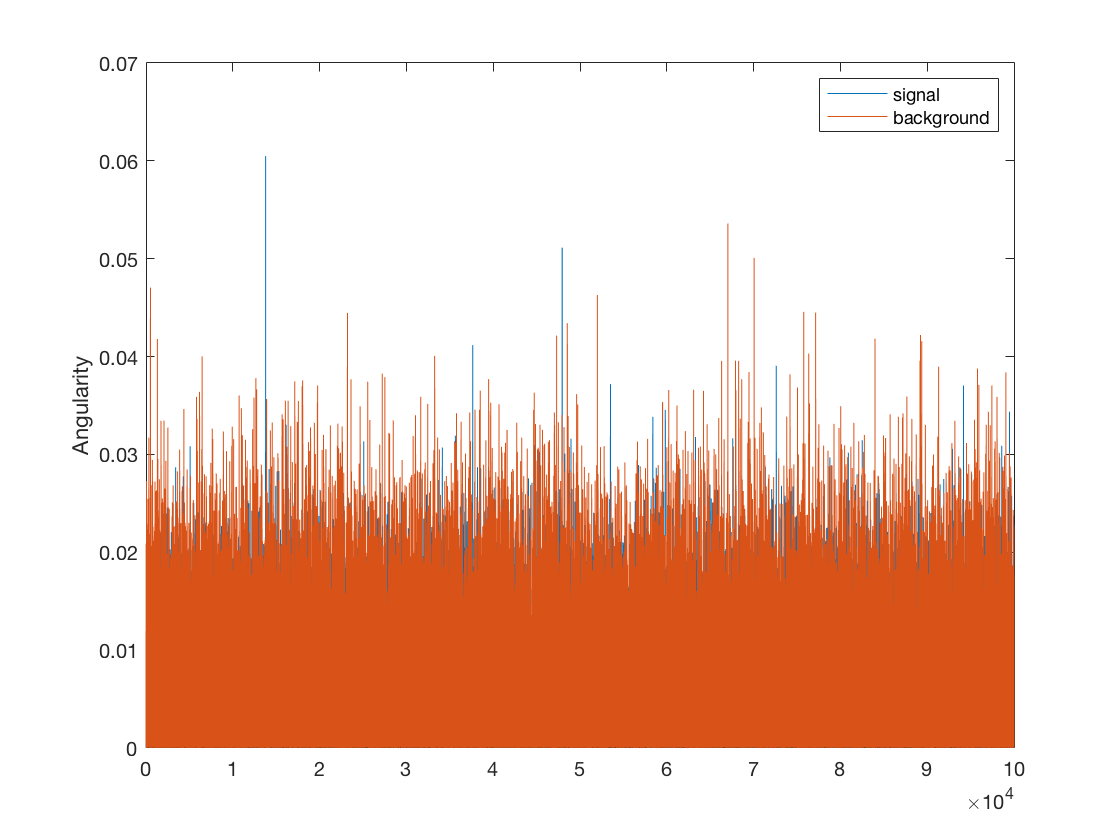

angSignal = signalData(8,1:100000);
plot(angSignal)
hold on
angBackground = backgroundData(8,1:100000);
plot(angBackground)
legend('signal','background')
hold off
ylabel('Angularity')

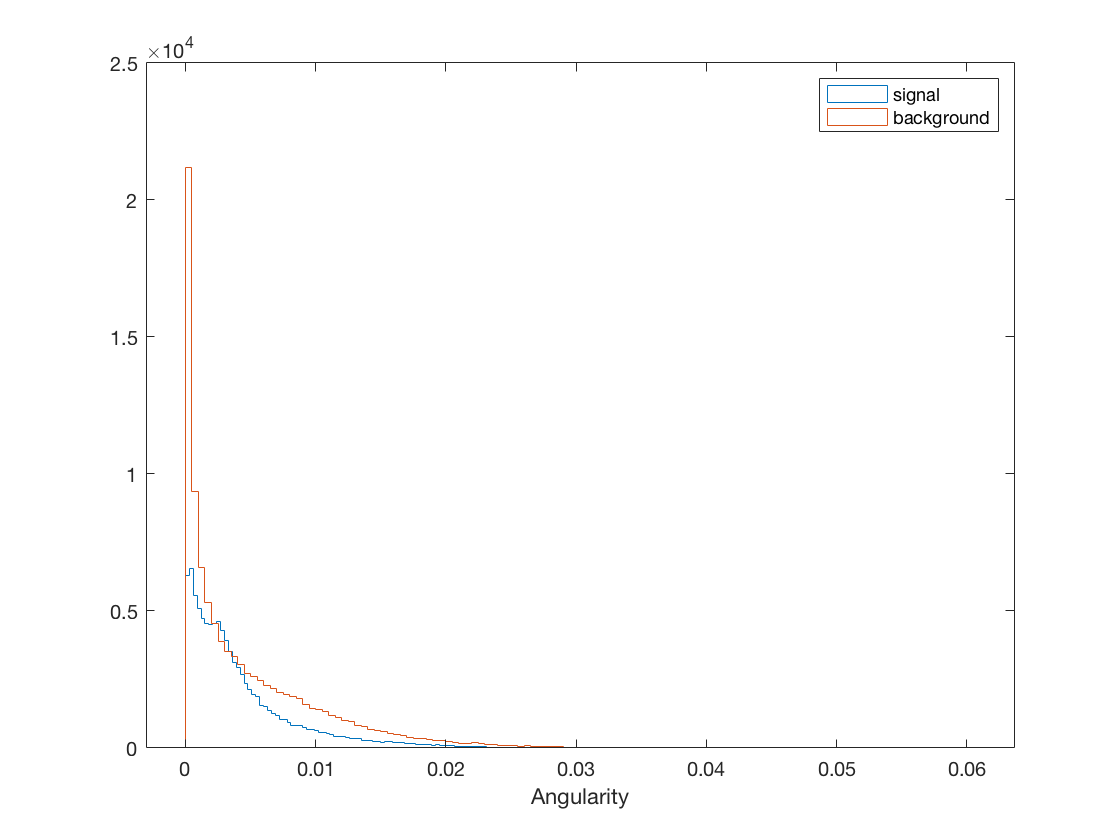


histogram(angSignal,'DisplayStyle','Stairs')
hold on
histogram(angBackground,'DisplayStyle','Stairs')
legend('signal','background')
hold off
xlabel('Angularity')

## t1

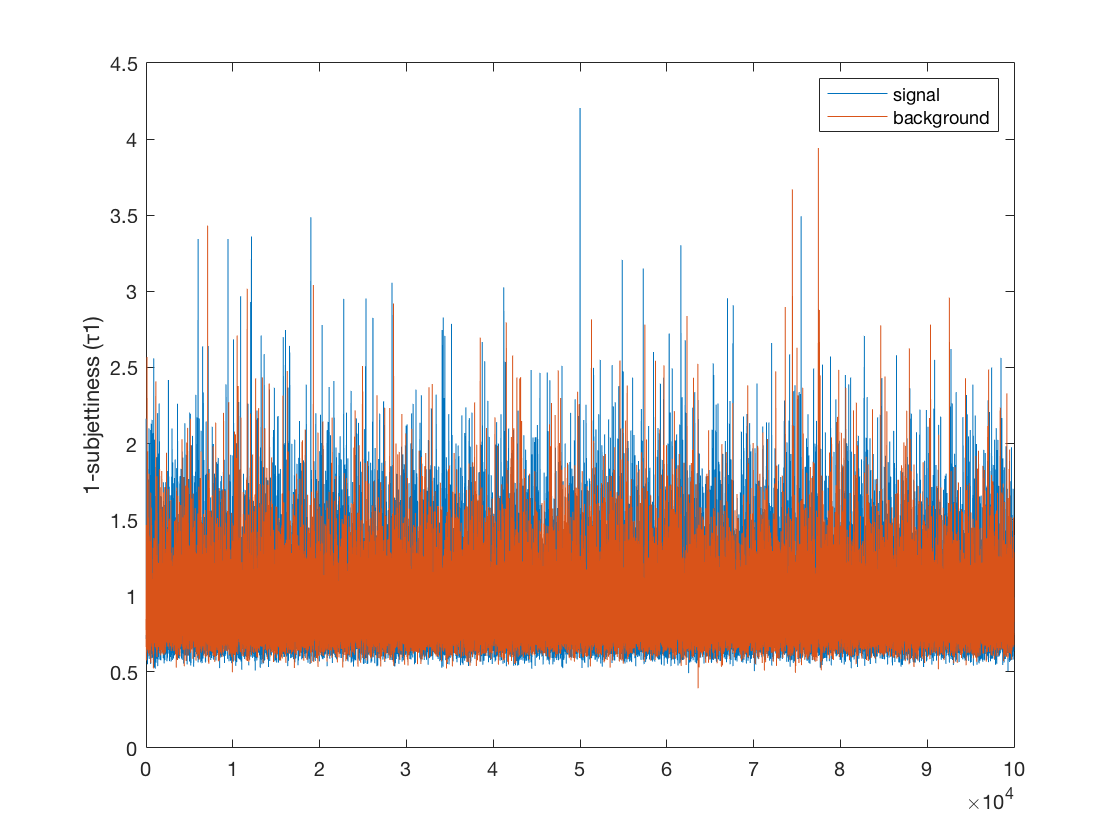

% τ1: 1-subjettiness
% τ0(ß)=∑(pt_i)*∆R
% τ1(ß)=(1/τ0(ß))∑(pt_i)*∆(R_a1)
t1Signal = signalData(9,1:100000);
plot(t1Signal)
hold on
t1Background = backgroundData(9,1:100000);
plot(t1Background)
legend('signal','background')
hold off
ylabel('1-subjettiness (τ1)')

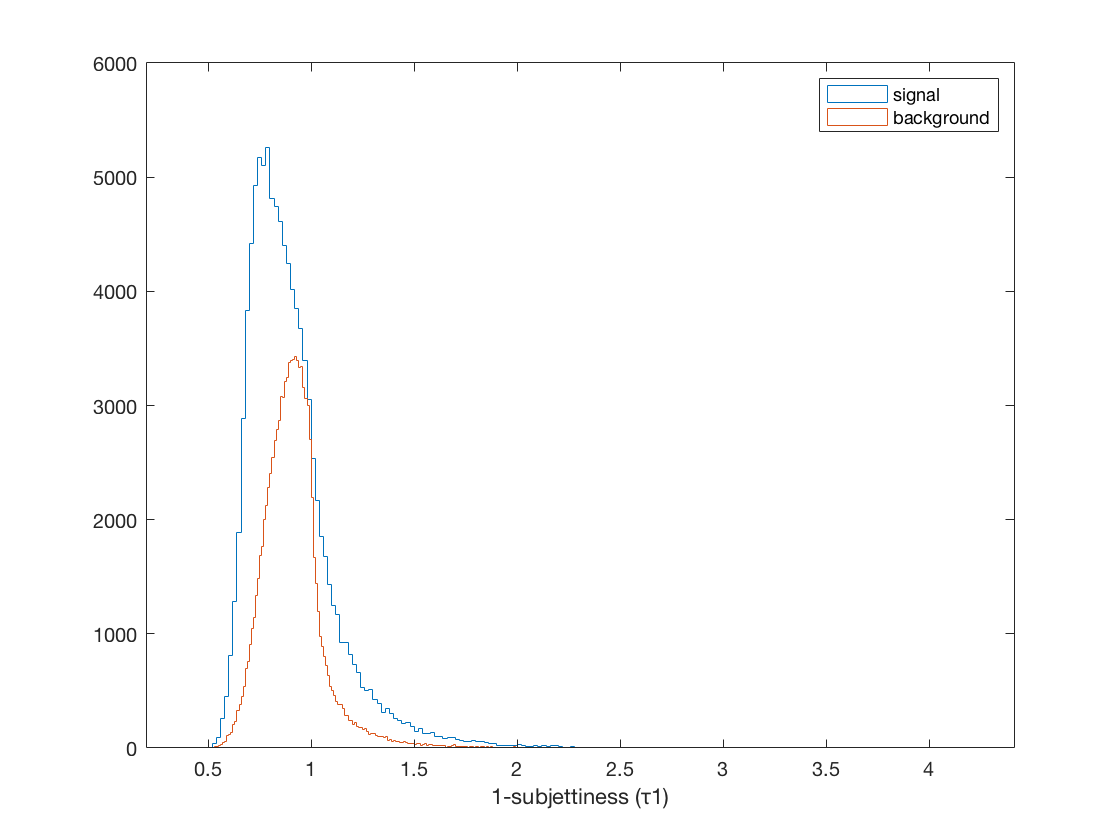

histogram(t1Signal,'DisplayStyle','Stairs')
hold on
histogram(t1Background,'DisplayStyle','Stairs')
legend('signal','background')
hold off
xlabel('1-subjettiness (τ1)')

## t2

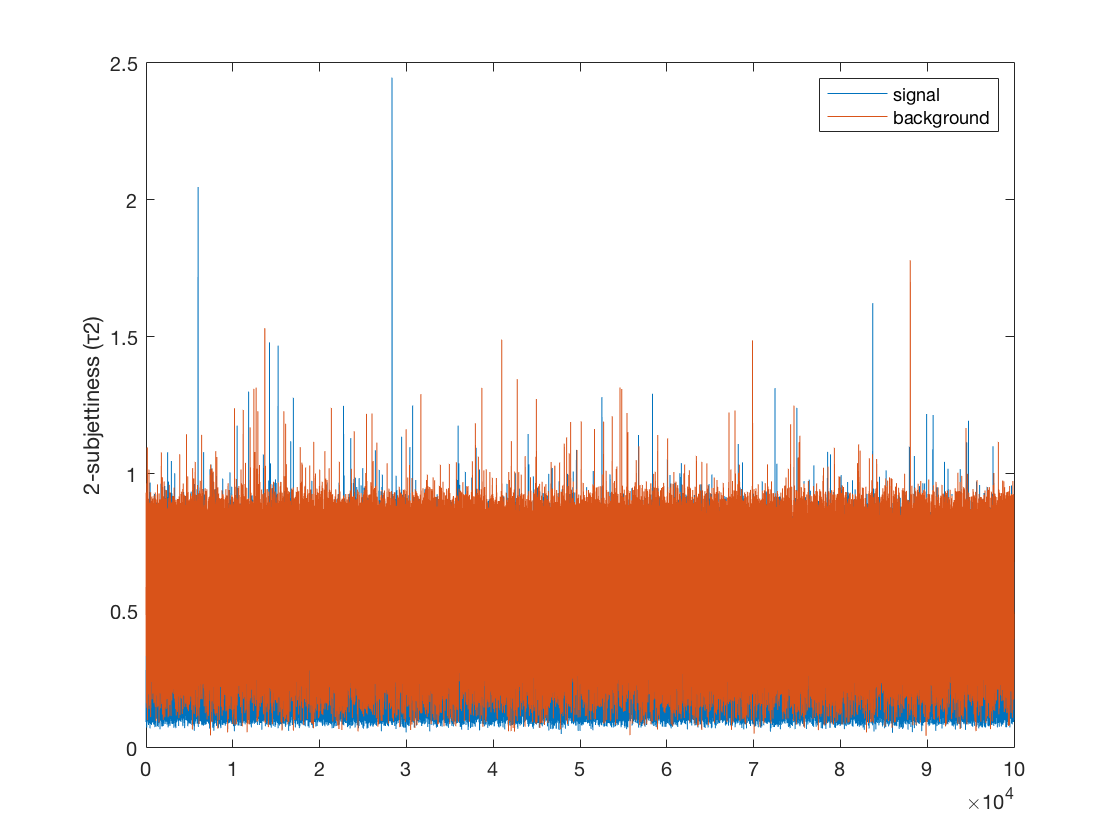

% τ2: 2-subjettiness
% τ2(ß)=(1/τ0(ß))∑(pt_i)*min(∆(R_a1),∆(R_a2))
t2Signal = signalData(10,1:100000);
plot(t2Signal)
hold on
t2Background = backgroundData(10,1:100000);
plot(t2Background)
legend('signal','background')
hold off
ylabel('2-subjettiness (τ2)')

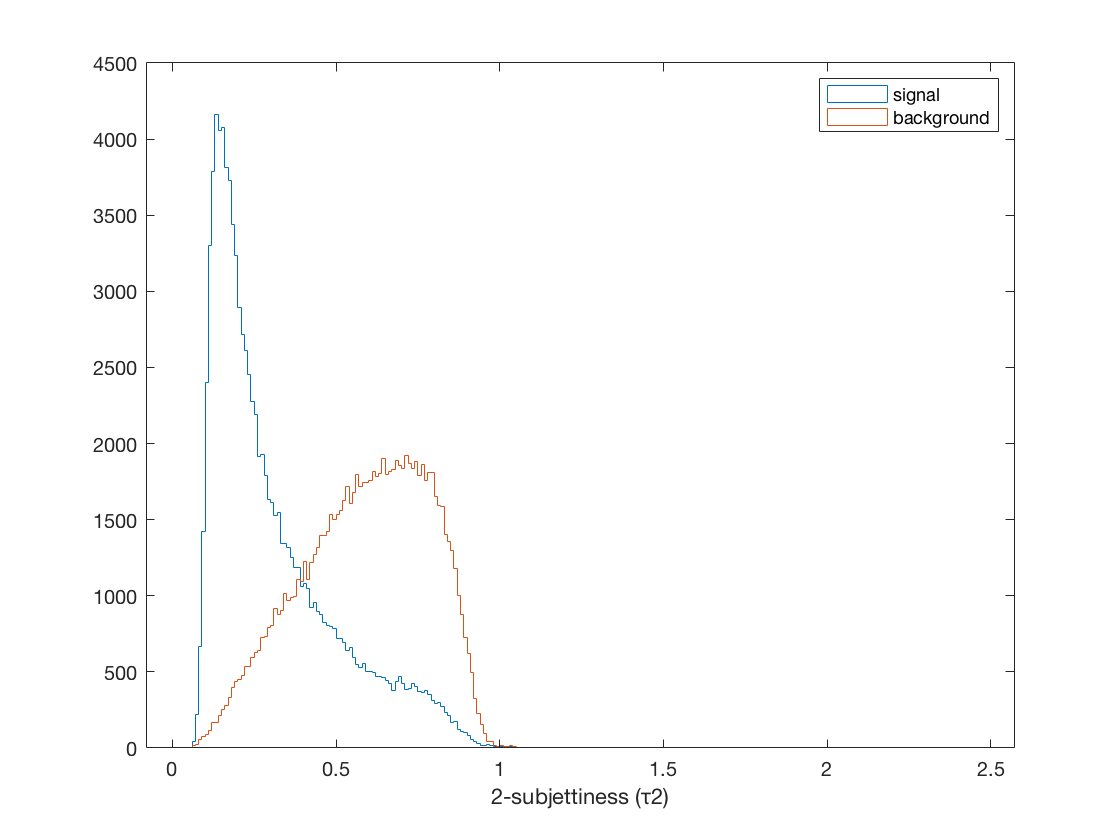


histogram(t2Signal,'DisplayStyle','Stairs')
hold on
histogram(t2Background,'DisplayStyle','Stairs')
legend('signal','background')
hold off
xlabel('2-subjettiness (τ2)')

## t3

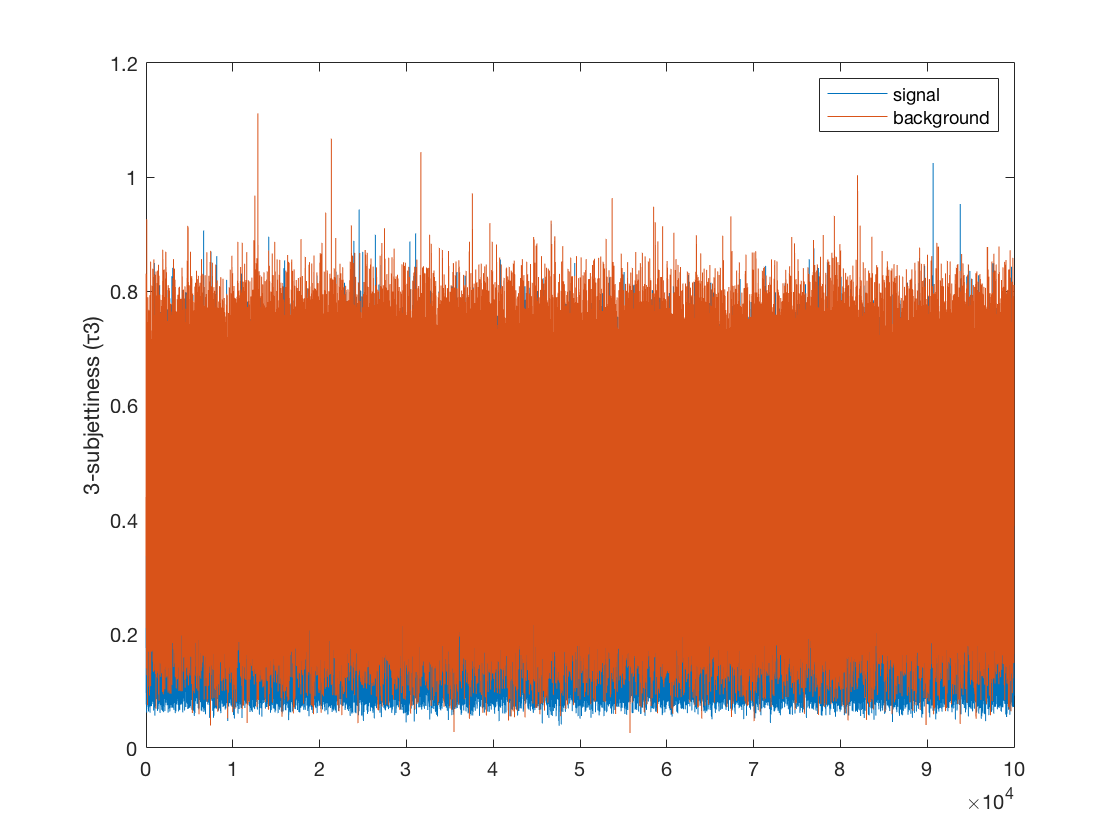

% τ3: 3-subjettiness
% τ2(ß)=(1/τ0(ß))∑(pt_i)*min(∆(R_a1),∆(R_a2),∆(R_a3))
t3Signal = signalData(11,1:100000);
plot(t3Signal)
hold on
t3Background = backgroundData(11,1:100000);
plot(t3Background)
legend('signal','background')
hold off
ylabel('3-subjettiness (τ3)')

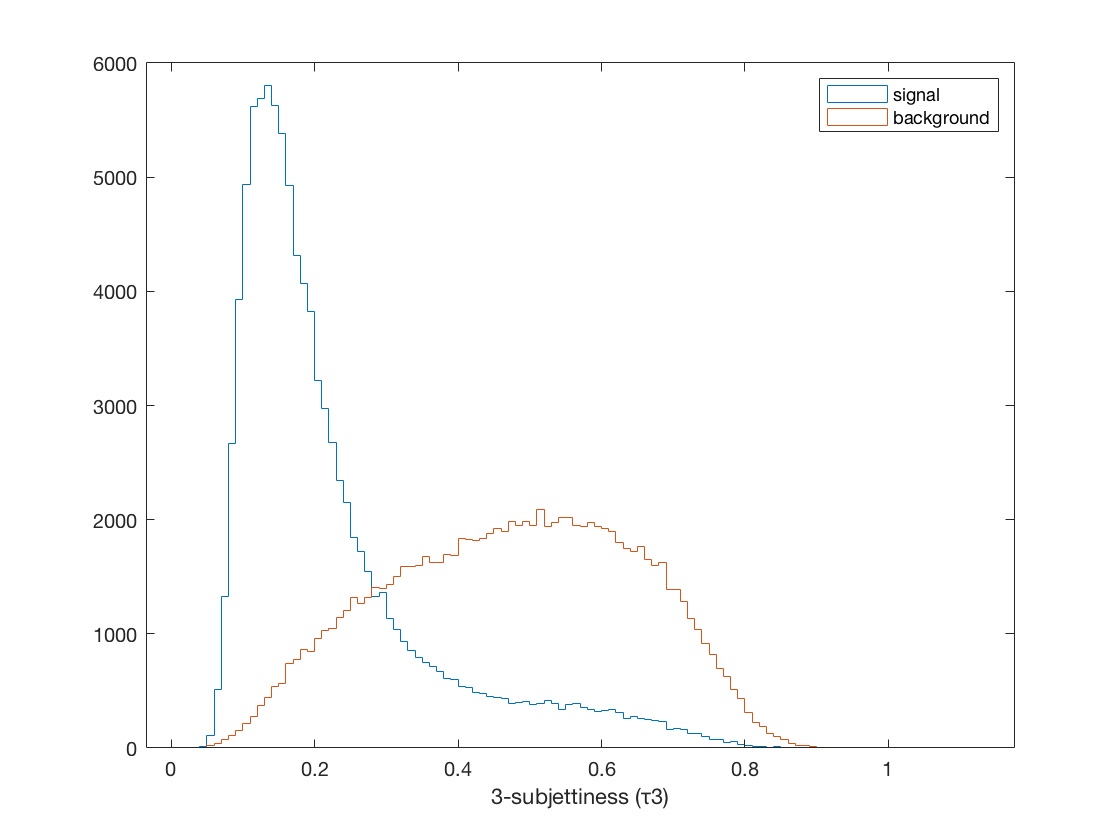


histogram(t3Signal,'DisplayStyle','Stairs')
hold on
histogram(t3Background,'DisplayStyle','Stairs')
legend('signal','background')
hold off
xlabel('3-subjettiness (τ3)')

## t21

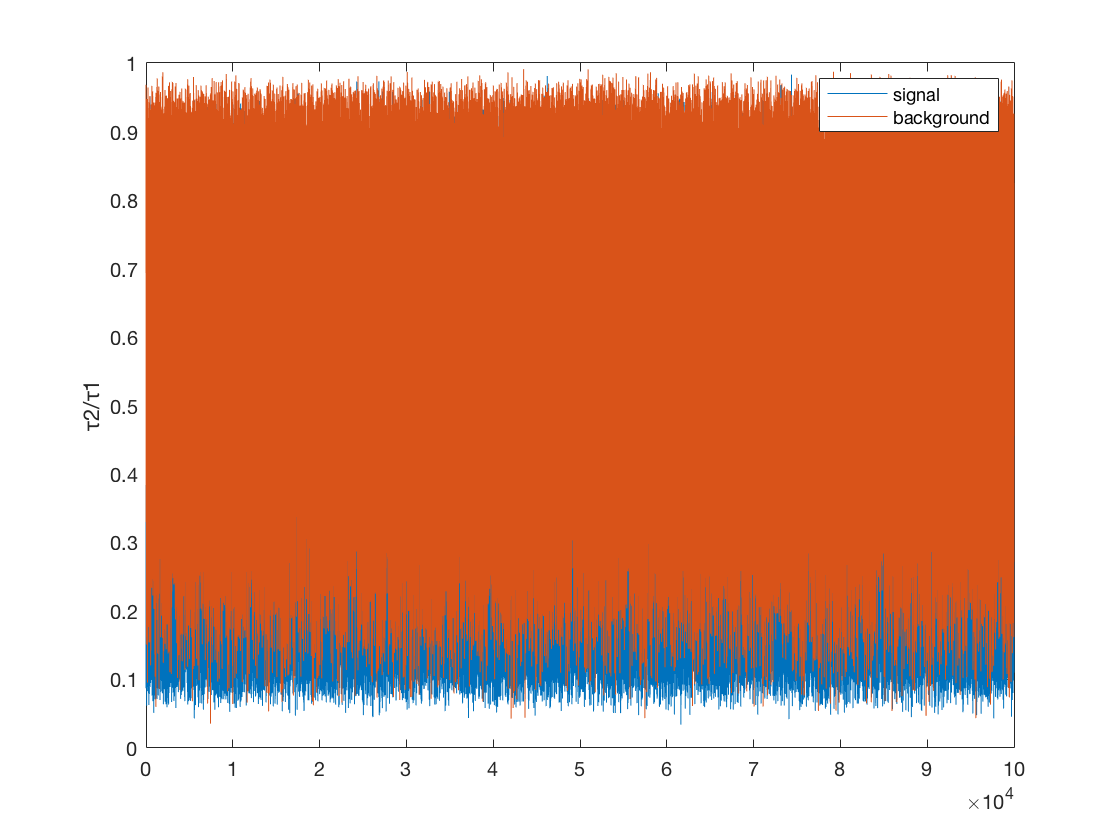

% τ21: τ2/τ1
t21Signal = signalData(12,1:100000);
plot(t21Signal)
hold on
t21Background = backgroundData(12,1:100000);
plot(t21Background)
legend('signal','background')
hold off
ylabel('τ2/τ1')

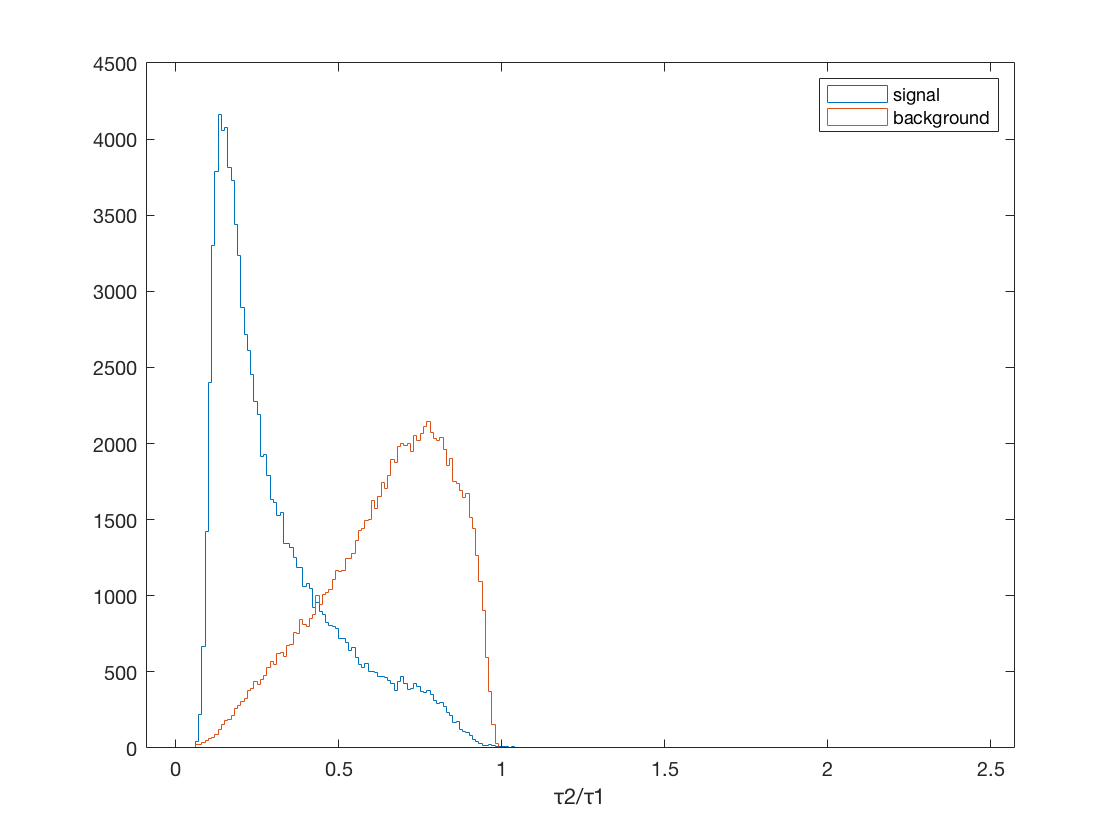


histogram(t2Signal,'DisplayStyle','Stairs')
hold on
histogram(t21Background,'DisplayStyle','Stairs')
legend('signal','background')
hold off
xlabel('τ2/τ1')

## t32

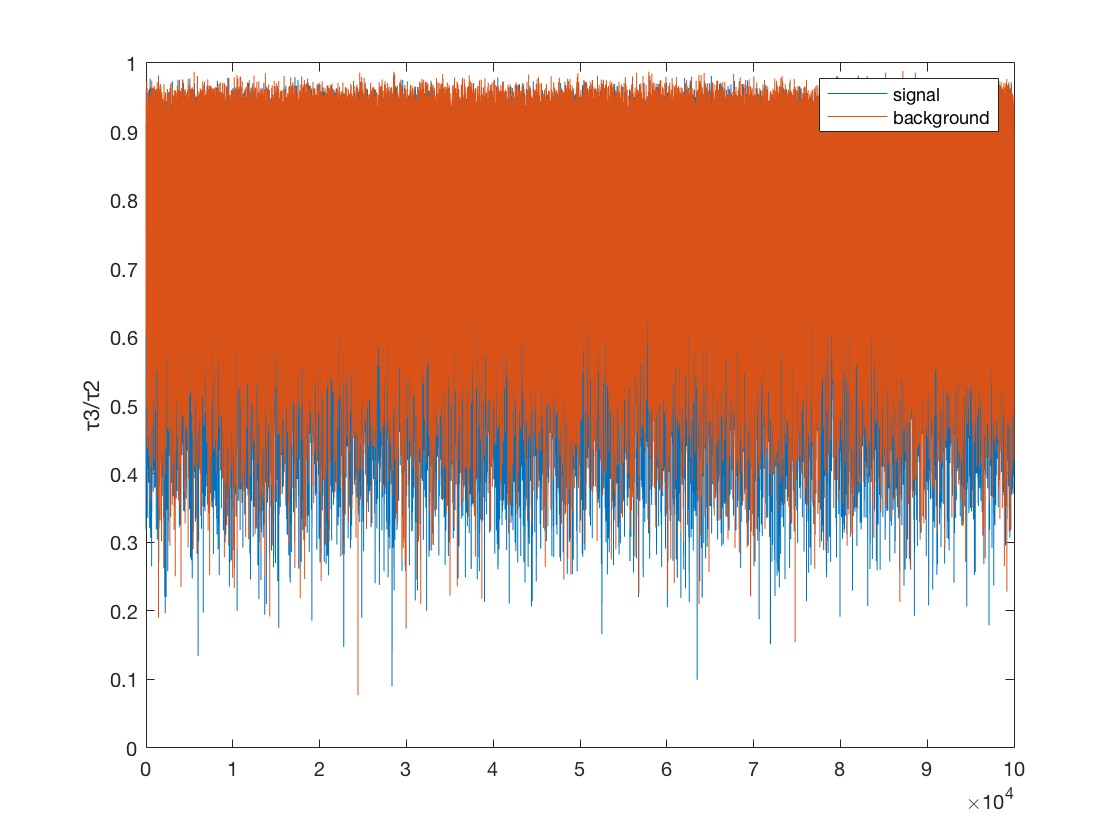

% τ32: τ3/τ2
t32Signal = signalData(13,1:100000);
plot(t32Signal)
hold on
t32Background = backgroundData(13,1:100000);
plot(t32Background)
legend('signal','background')
hold off
ylabel('τ3/τ2')

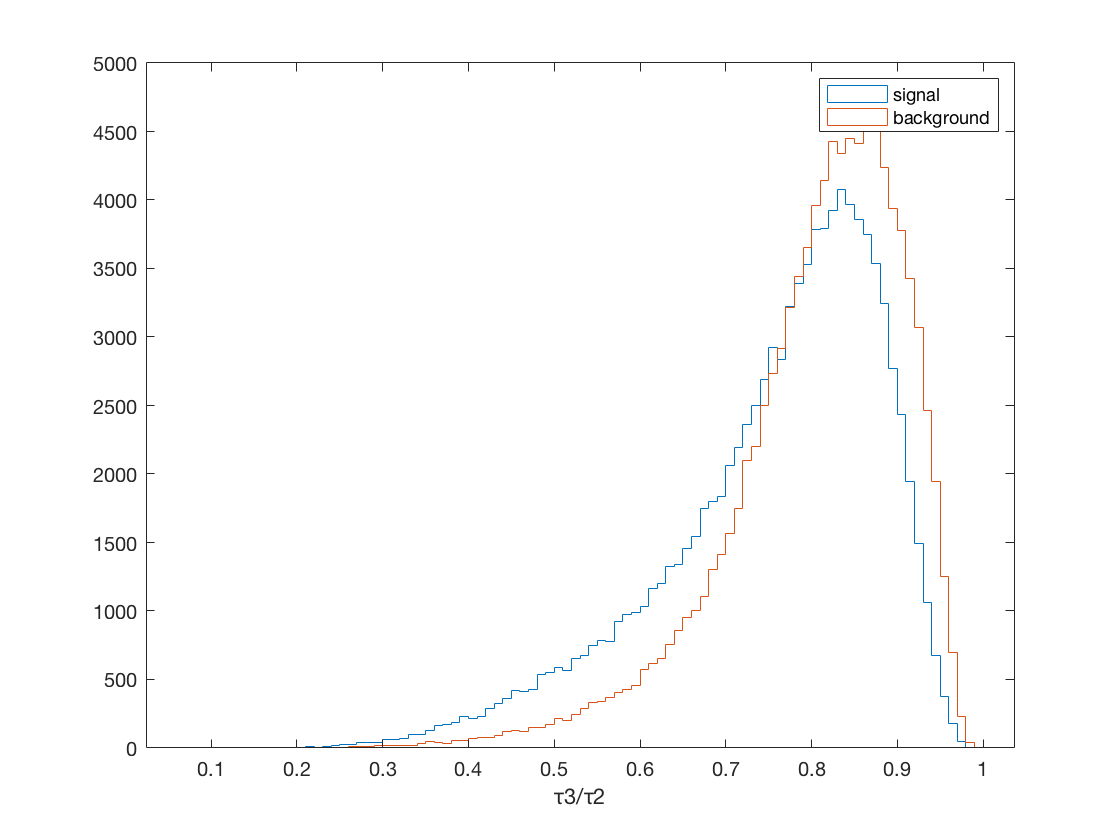


histogram(t32Signal,'DisplayStyle','Stairs')
hold on
histogram(t32Background,'DisplayStyle','Stairs')
legend('signal','background')
hold off
xlabel('τ3/τ2')

## KtDeltaR

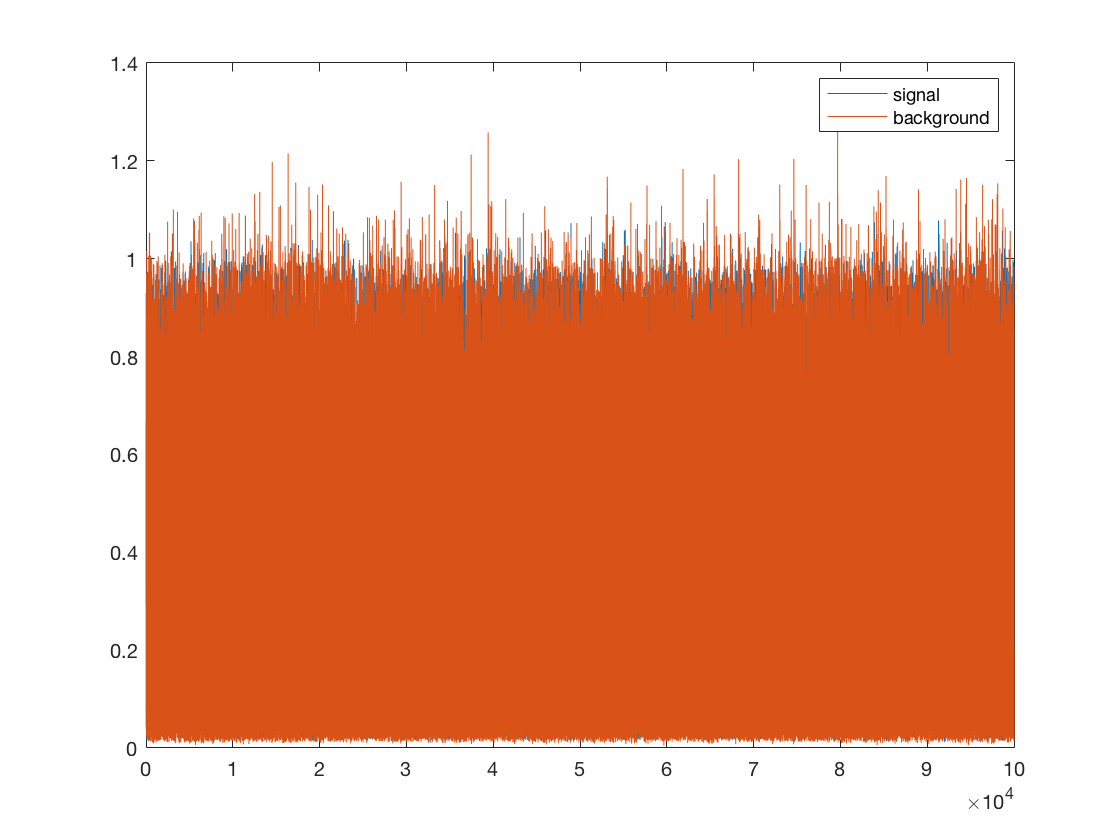

% kt∆R: ∆R(angular distance) of two subjects within the large-R jet
ktDeltaRSignal = signalData(14,1:100000);
plot(ktDeltaRSignal)
hold on
ktDeltaRBackground = backgroundData(14,1:100000);
plot(ktDeltaRBackground)
legend('signal','background')
hold off

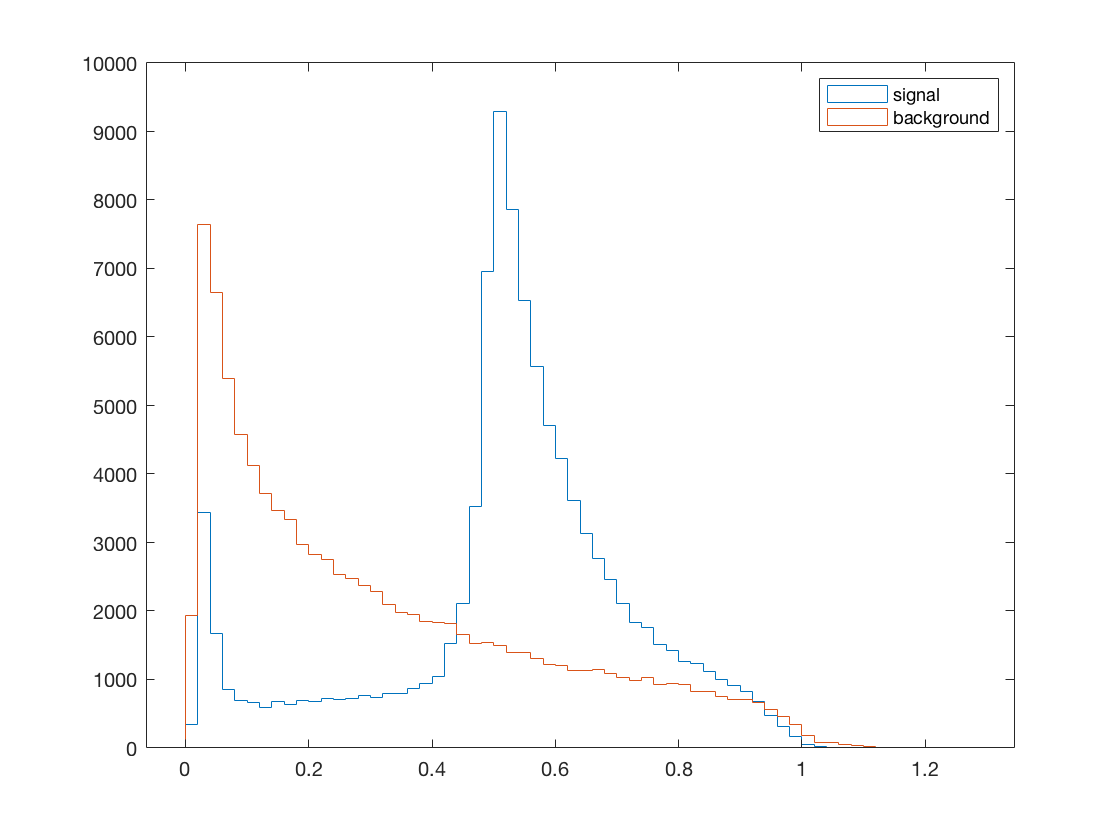

histogram(ktDeltaRSignal,'DisplayStyle','Stairs')
hold on
histogram(ktDeltaRBackground,'DisplayStyle','Stairs')
legend('signal','background')
hold off